# Approximating a Sinusoid as A Polynomial

clc; clear; close all;

addpath('BuildTables');

## Problem

Consider the function:


$$x\left(t\right)=A\;\mathrm{sin}\left(\omega \;t+\phi \right)$$


We wish to find explicit formulas for the coefficients of a polynomial in terms of $t$.

That is we want a formula for $S_k$:


$$x\left(t\right)=\sum_k S_k {\left(\omega ,\phi \right)t}^k$$


## Simple Taylor Expansion

We start with a simple Taylor expansion:

**Lemma 1:**


$$A\;\mathrm{sin}\left(\omega \;t+\phi \right)=A\sum_{k=0}^{\infty } \frac{{\left(-1\right)}^k {\left(\omega \;t+\phi \right)}^{2k+1} }{\left(2k+1\right)!}$$


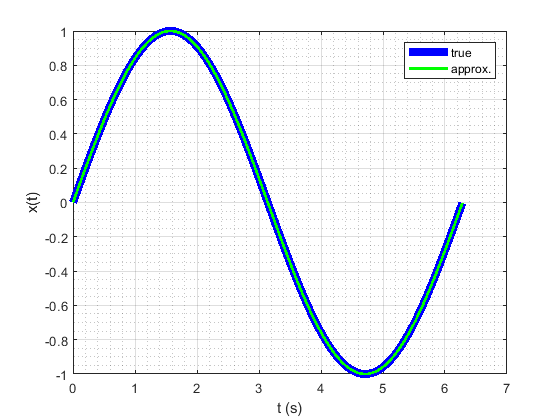

TestLemma1();

## Application of the Binomial Theorem

Now we apply binomial expansion to the ${\left(\omega \;t+\phi \right)}^{2k+1}$ term arising in Lemma 1:


$${\left(\omega \;t+\phi \right)}^{2k+1} =\sum_{j=0}^{2k+1} C_j^{2k+1} \phi {\;}^{2k+1-j} \omega {\;}^j t^j$$



$$x\left(t\right)=A\sum_{k=0}^{\infty } \frac{{\left(-1\right)}^k }{\left(2k+1\right)!}$$

$$\sum_{j=0}^{2k+1} C_j^{2k+1} \phi {\;}^{2k+1-j} \omega {\;}^j t^j$$



$$x\left(t\right)=A\sum_{k=0}^{\infty } \sum_{j=0}^{2k+1} \frac{{\left(-1\right)}^k }{\left(2k+1\right)!}C_j^{2k+1} \phi {\;}^{2k+1-j} \omega {\;}^j t^j$$


**Lemma 2:**


$$A\;\mathrm{sin}\left(\omega \;t+\phi \right)=A\sum_{k=0}^{\infty } \sum_{j=0}^{2k+1} \frac{{\left(-1\right)}^k }{\left(2k+1\right)!}C_j^{2k+1} \phi {\;}^{2k+1-j} \omega {\;}^j t^j$$


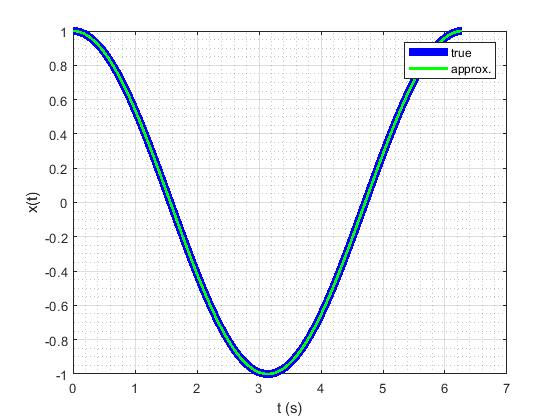

TestLemma2();

## Rearranging the Summation

Now we wish to rearrange the summation from Lemma 2 into a sum in terms of powers of $t$.

The sum from Lemma 2 was:


$$A\;\mathrm{sin}\left(\omega \;t+\phi \right)=A\sum_{k=0}^{\infty } \sum_{j=0}^{2k+1} \frac{{\left(-1\right)}^k }{\left(2k+1\right)!}C_j^{2k+1} \phi {\;}^{2k+1-j} \omega {\;}^j t^j$$


An approximate version can be considered to make the rearrangement of the summation more intuitive:


$$A\;\mathrm{sin}\left(\omega \;t+\phi \right)\approx A\sum_{k=0}^K \sum_{j=0}^{2k+1} \frac{{\left(-1\right)}^k }{\left(2k+1\right)!}C_j^{2k+1} \phi {\;}^{2k+1-j} \omega {\;}^j t^j$$


To rearrange the sum, note that the k and j indicies inside the summation loop form a pattern.  For example, consider the (k,j) tuples formed inside the inner summation loop for K = 2

(0,0) (0,1)

(1,0) (1,1) (1,2) (1,3)

(2,0) (2,1) (2,2) (2,3) (2,4) (2,5)

This makes evident the fact that the summation can be broken into an even j and an odd j part:

Even j:

(0,0)

(1,0) (1,2)

(2,0) (2,2) (2,4)

Odd j:

(0,1)

(1,1) (1,3)

(2,1) (2,3) (2,5)

The full summation can be computed by summing the intermediate results from both these triangular arrays.  Note that because the j index represents powers of t, the even summation part representes the cosine component of the wave and the odd summation part represents the sine component.

It is trivial to write loops over these two triangular arrays (see TestLemma3() for code).

Therefore:

**Lemma 3:**


$$A\;\mathrm{sin}\left(\omega \;t+\phi \right)=\sum_{j=0}^{\infty } \sum_{k=j}^{\infty } \mu \;\left(2j,k\right)t^{2j} +\sum_{j=0}^{\infty } \sum_{k=j}^{\infty } \mu \;\left(2j+1,k\right)t^{2j+1}$$



$$\mu \left(j,k\right)=A\frac{{\left(-1\right)}^k }{\left(2k+1\right)!}C_j^{2k+1} \phi {\;}^{2k+1-j} \omega {\;}^j$$


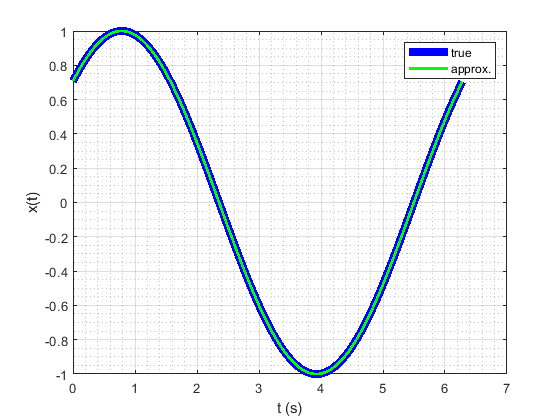

TestLemma3();

## Manipulating Lemma 3

Now we wish to manipulate Lemma 3 into a convienient matrix form which allows easily changing amplitude, frequency, or phase:


$$A\;\mathrm{sin}\left(\omega \;t+\phi \right)=\sum_{j=0}^{\infty } \sum_{k=j}^{\infty } \mu \;\left(2j,k\right)t^{2j} +\sum_{j=0}^{\infty } \sum_{k=j}^{\infty } \mu \;\left(2j+1,k\right)t^{2j+1}$$



$$\mu \left(j,k\right)=A\frac{{\left(-1\right)}^k }{\left(2k+1\right)!}C_j^{2k+1} \phi {\;}^{2k+1-j} \omega {\;}^j$$


Remove the $\phi \;$and $\omega \;$terms from the definition of $\mu$:


$$A\;\mathrm{sin}\left(\omega \;t+\phi \right)=A\sum_{j=0}^{\infty } t^{2j} \omega {\;}^{2j} \sum_{k=j}^{\infty } \mu \;\left(2j,k\right)\Phi \;\left(2j,k\right)+A\sum_{j=0}^{\infty } t^{2j+1} \omega {\;}^{2j+1} \sum_{k=j}^{\infty } \mu \;\left(2j+1,k\right)\Phi \;\left(2j+1,k\right)$$



$$\mu \left(j,k\right)=\frac{{\left(-1\right)}^k }{\left(2k+1\right)!}C_j^{2k+1}$$



$$\Phi \;\left(j,k\right)=\phi {\;}^{2k+1-j}$$


Now define new functions, which give the elements of four upper triangular matricies:


$$\mu_E \left(j,k\right)=\left\lbrace \begin{array}{cc}
\frac{{\left(-1\right)}^k }{\left(2k+1\right)!}C_{2j}^{2k+1}  & k\ge j\\
0 & o\ldotp w\ldotp 
\end{array}\right.\;\;$$



$$\mu_O \left(j,k\right)=\left\lbrace \begin{array}{cc}
\frac{{\left(-1\right)}^k }{\left(2k+1\right)!}C_{2j+1}^{2k+1}  & k\ge j\\
0 & o\ldotp w\ldotp 
\end{array}\right.$$



$$\Phi_E \left(j,k,\phi \right)=\left\lbrace \begin{array}{cc}
\phi {\;}^{2k+1-2j}  & k\ge j\\
0 & o\ldotp w\ldotp 
\end{array}\right.$$



$$\Phi_O \left(j,k,\phi \right)=\left\lbrace \begin{array}{cc}
\phi {\;}^{2k+1-\left(2j+1\right)} =\phi {\;}^{2k-2j}  & k\ge j\\
0 & o\ldotp w\ldotp 
\end{array}\right.$$


Now note that the above sum can be expressed convieniently in matrix notation:

**Lemma 4:**


$$A\;\mathrm{sin}\left(\omega \;t+\phi \right)=T{\;}_E K{\;}_E +T_O K_O$$


If only one time point $t$ is to be evaluated:


$$T_E =\left\lbrack \begin{array}{ccccc}
t^0  & t^2  & t^4  & \cdots  & t^{2K} 
\end{array}\right\rbrack \in M^{1\times \;K}$$



$$T_O =\left\lbrack \begin{array}{ccccc}
t^1  & t^3  & t^5  & \cdots  & t^{2K+1} 
\end{array}\right\rbrack \in M^{1\times K}$$


If $N$ time points $t_0 \cdots t_N$are to be evaluated:


$$T_E =\left\lbrack \begin{array}{ccccc}
t_0^0  & t_0^2  & t_0^4  & \cdots  & t_0^{2K} \\
t_1^0  & t_1^2  & t_1^4  & \cdots  & t_1^{2K} \\
t_2^0  & t_2^2  & t_2^4  & \cdots  & t_2^{2K} \\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
t_N^0  & t_N^2  & t_N^4  & \cdots  & t_N^{2K} 
\end{array}\right\rbrack \in M^{N\times \;K}$$



$$T_O =\left\lbrack \begin{array}{ccccc}
t_0^1  & t_0^3  & t_0^5  & \cdots  & t_0^{2K+1} \\
t_1^1  & t_1^3  & t_1^5  & \cdots  & t_1^{2K+1} \\
t_2^1  & t_2^3  & t_2^5  & \cdots  & t_2^{2K+1} \\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
t_N^1  & t_N^3  & t_N^5  & \cdots  & t_N^{2K+1} 
\end{array}\right\rbrack \in M^{N\times \;K}$$



$$K{\;}_E =\mathrm{diag}\left(\left(M_E \circ \Phi {\;}_E \right)\Omega {\;}_E \right)$$



$$K{\;}_O =\mathrm{diag}\left(\left(M_O \circ \Phi {\;}_O \right)\Omega {\;}_O \right)$$



$$M_E =\left\lbrack \mu_E \left(j,k\right)\right\rbrack \in M^{K\times \;K}$$



$$M_O =\left\lbrack \mu_O \left(j,k\right)\right\rbrack \in M^{K\times \;K}$$



$$\Phi_E =\left\lbrack \Phi_E \left(j,k,\phi \;\right)\right\rbrack \in M^{K\times \;K}$$



$$\Phi_O =\left\lbrack \Phi_O \left(j,k,\phi \;\right)\right\rbrack \in M^{K\times \;K}$$



$$\omega_E =\left\lbrack \begin{array}{cccc}
\omega^0  & 0 & \cdots  & 0\\
\omega^0  & \omega^2  & \cdots  & 0\\
\vdots  & \vdots  & \ddots  & \vdots \\
\omega^0  & \omega^2  & \cdots  & \omega^{2K} 
\end{array}\right\rbrack$$



$$\omega_O =\left\lbrack \begin{array}{cccc}
\omega^1  & 0 & \cdots  & 0\\
\omega^1  & \omega^3  & \cdots  & 0\\
\vdots  & \vdots  & \ddots  & \vdots \\
\omega^1  & \omega^3  & \cdots  & \omega^{2K+1} 
\end{array}\right\rbrack$$


As an optimization, note that


$$K{\;}_E =\mathrm{diag}\left(\left(M_E \circ \Phi {\;}_E \right)\Omega {\;}_E \right)$$



$$K{\;}_O =\mathrm{diag}\left(\left(M_O \circ \Phi {\;}_O \right)\Omega {\;}_O \right)$$


Can be more efficiently computed as:


$$K_E =\mathrm{sum}\left(M_E \circ \Phi {\;}_E \circ \Omega_E^T ,2\right)$$



$$K_O =\mathrm{sum}\left(M_O \circ \Phi {\;}_O \circ \Omega_O^T ,2\right)$$


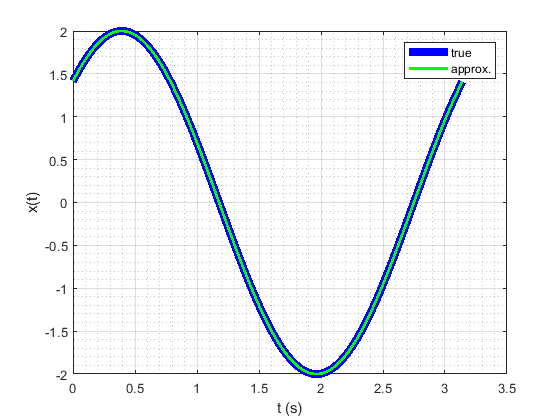

TestLemma4();

## Biased Multisine Expansion

Lemma 4 can be used to evaluate a multisine, defined by a vector of Amplitudes, $A$, a vector of angular frequencies, $\omega$, and a vector of phaseshifts, $\phi$.

kappa_multisine_even_matrix =     3.0020
   -6.6579
    4.7975
   -1.4327
    0.2301
   -0.0230
    0.0016
   -0.0001
    0.0000
   -0.0000


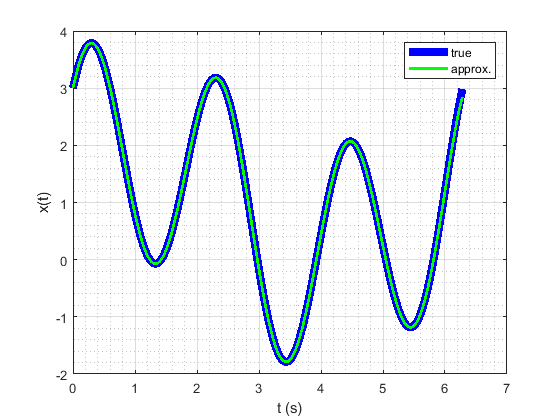

TestKappaSine